clear all;close all;

basePath = 'C:\Users\sgrc-325\Desktop\';

% fileNames = {'240828_rtk_r5_kinematic.CSV'};
fileNames = {'240828_rtk_r3_kinematic.CSV'};
% fileNames = {'240828_rtk_r3_2m_kinematic.CSV'};
allData = [];

for i = 1:length(fileNames)
    filePath = fullfile(basePath, fileNames{i});
    tempData = readtable(filePath, 'Delimiter', ',', 'ReadVariableNames', false);
    allData = [allData; tempData]; % 將每個表格資料合併
end

allData(1:120,:)=[];

moData=allData;

mo=[moData.Var3 moData.Var3 moData.Var3 moData.Var4 moData.Var5 moData.Var6 moData.Var7 moData.Var8 moData.Var9 moData.Var10 moData.Var11 moData.Var12 moData.Var13 moData.Var14 moData.Var15];

[No,~]=size(mo);

date= moData.Var1;
time_gps=moData.Var2;
lat=mo(:,3);
lon=mo(:,4);
alt=mo(:,5);
Q=mo(:,6);
sats=mo(:,7);
sdn=mo(:,8);
sde=mo(:,9);
sdne=mo(:,10);
sdeu=mo(:,11);
sdun=mo(:,12);
age=mo(:,13);
ratio=mo(:,14);

stdd=std(mo)'; %看標準差

close all
tt = time_gps;

% figure(7)
% plot(lon)
% figure(8)
% plot(lat)
% figure(9)
% plot(lon,lat,'.')
% axis equal;


close all
% 設定投影參數，使用台灣西部二度分帶的 TWD97 座標系
latlon = [lat, lon]; % 經緯度資料組合為矩陣
twd97 = projcrs(3826); % TWD97 座標系

% 使用 projfwd 進行經緯度到座標的轉換
[x, y] = projfwd(twd97, latlon(:,1), latlon(:,2));

x=x*0.01; %m to cm
y=y*0.01;
altcm=alt*0.01;

x=x-x(1);
y=y-y(1);
altcm=altcm-altcm(1);
x1=[];y1=[];altcm1=[];

for i=1:No
    if(Q(i)==1)
        x1(end+1)=x(i);
        y1(end+1)=x(i);
        altcm1(end+1)=altcm(i);
    end
end

% figure(1)
% p=plot(x1,y1,'o');
% axis equal;
% pgca = gca; % 取得當前座標軸
% agca.XAxis.Exponent = 0; % 禁止顯示科學記數法
% agca.YAxis.Exponent = 0;
% xtickformat('%.3f'); % 軸顯示到小數點後3位
% ytickformat('%.3f');
% p.DataTipTemplate.DataTipRows(1).Format = '%.8f'; % 軸DataTip顯示到小數點後8位
% p.DataTipTemplate.DataTipRows(2).Format = '%.8f';

std(x1)

ans = 0.0061

std(y1)

ans = 0.0061

std(altcm1)

ans = 0.0042

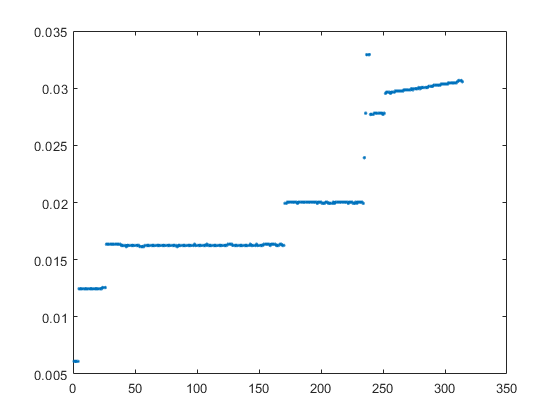


figure(2)
plot(x1,'.')

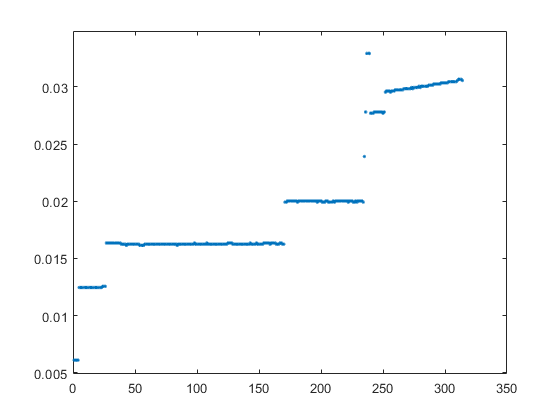

figure(3)
plot(y1,'.')

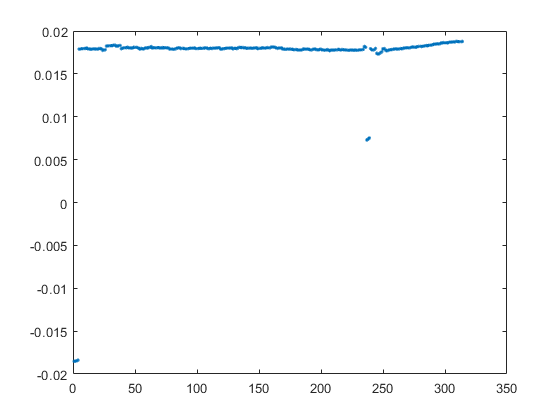

figure(4)
plot(altcm1,'.')

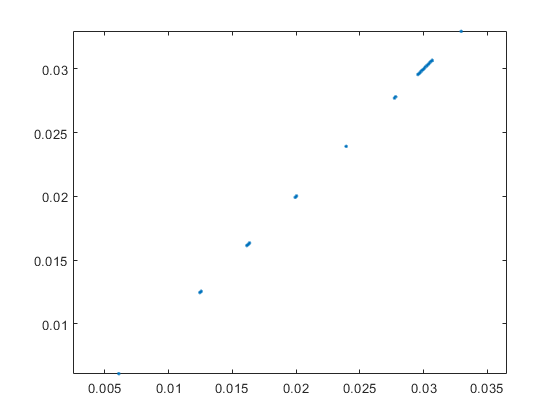


figure(5)
plot(x1,y1,'.')
axis equal;

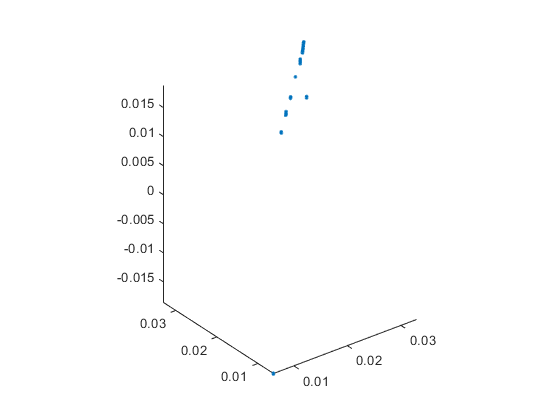


figure(6)
plot3(x1,y1,altcm1,'.')
axis equal;